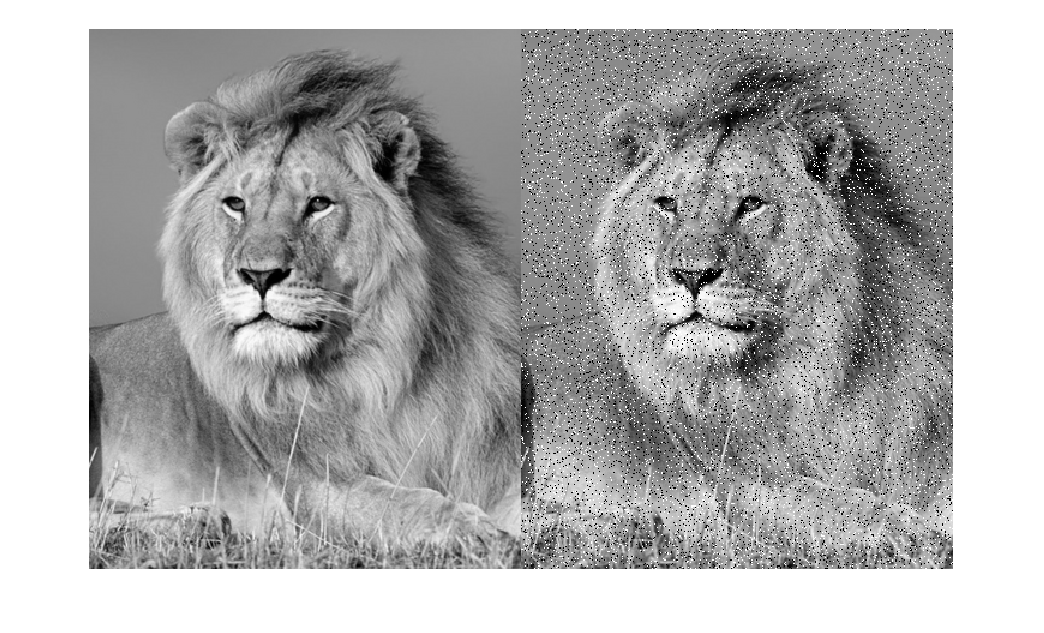

I = rgb2gray(imread('leon.png'));
SALT = imnoise(I,'salt & pepper',0.1);
montage({I,SALT});

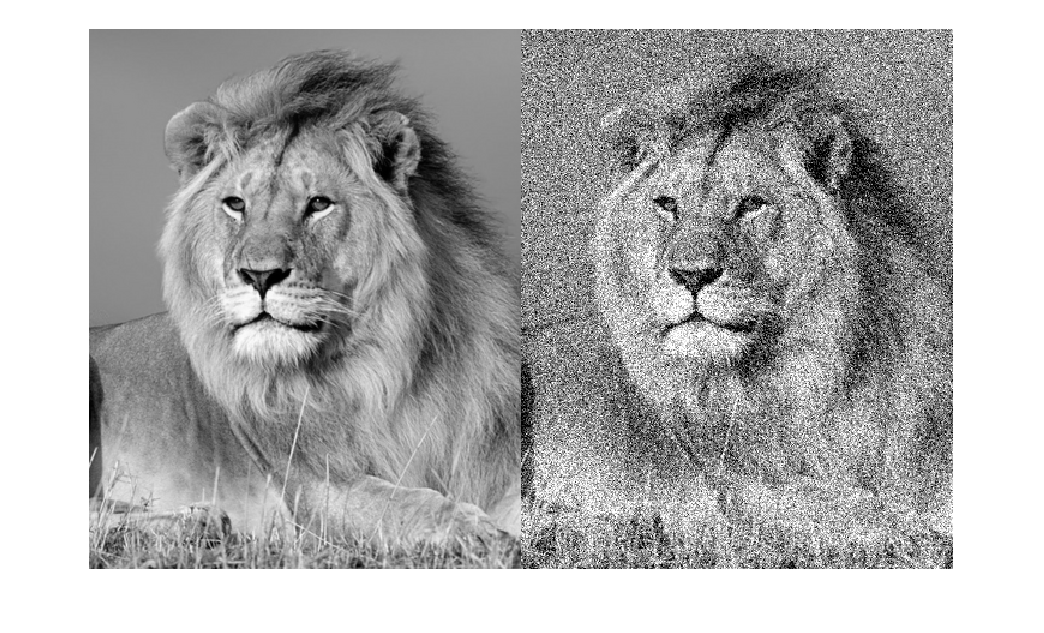

GAUSS = imnoise(I,"gaussian",0,10/255);
montage({I,GAUSS});

h = [1,1,1;1,1,1;1,1,1]/9; %%normalitzar perque la suma=1
F = imfilter(N,h);

Unrecognized function or variable 'N'.

montage({I,F});

k = fspecial('average',10);
%k = fspecial('gaussian',5);
F = imfilter(N,k);
montage({I,F});

MED = medfilt2(SALT);
MED2 = medfilt2(MED);
MED3 = medfilt2(MED2);
montage({I,MED,MED2,MED3});

%testeo = [0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1 1];
%testeo = testeo/sum(testeo,'all');
testeo = fspecial('motion',100,45);
MOVIMENT = imfilter(I,testeo);
montage({I,MOVIMENT});

F = stdfilt(I);
imshow(F,[]);

h=[1 1 1; 0 0 0; -1 -1 -1]; %% canvis horitzontals
                            %% h' canvis verticals
                            %% h + h' els juntem
GV = imfilter(I,h);
GV2 = imfilter(I,h');
GV3 = imfilter(I,h+h');

montage({I,GV,GV2,GV3});

F = nlfilter(SALT,[3 3],@filtrado);
montage({SALT,F});

A = imread('Pin 1.jpg');
E = edge(A,'Canny',0.5,sqrt(2));
SUM = sum(A(:))
imshow(E);